# EE 451 Final Exam

# Lisa Jacklin

## Problem 1

%initial setup for problem 1:
f = 0:2500; %this is the frequency range in which the passband is located

%since a delta w is not given, I will assume for the moment that the
%transition width is pi/50, which allows us to create a baseline M value to
%begin with.

%problem 1 part a: length of M of the FIR filter
M = 4*pi/(pi/50) 

M = 200.0000


%problem 1 part b: cuttoff frequency wc of the FIR filter
Fs = 10000; Ts = 1/Fs; %sampling frequency 10kHz, and sampling time of 10ms.
%note that Fs is now pi so, 

wc = pi/4 %2500 is 1/4 of the Fs given.

wc = 0.7854

%so pi/4 is the cuttoff for this filter.

%problem 1 part c: compute the values for the unite sample response hlpn
%for the filter. 
%now, I can use ideal_lp which was built in class/lab to compute the
%following values
hlpn = ideal_lp(wc, M); %this creates the original idea lowpass
hm = rectwin(M); %we want the window to be the length of M

h = hlpn .* hm; %this gives us the filtered lowpass we are looking for.

%now that we have the FIR filter designed based on our original items, to
%get the unit sample values we are looking for, we must put them through
%another function built in class/lab called freqz_m which will give us the
% values we are looking for.

%please note that [1] is here because for a FIR causal filter, the
%denominator will always be 1!
%[db,mag,pha,grd,w] = freqz_m(h,[1]); %this is what I should be able to
%call but having a matrix issue...

%problem 1 part d:

%if I was able to obtain the freqz_m above, I found obtain the Attenuation
%in the stopband via the following program:

%delta_w = 2*pi/1000;
%df = 0.02*pi;
% ws1 = wc1 - (df/2);
% As = -round(max(db(1:1:ws1/delta_w-1))) 


%problem 1 part e: what is the stopband attenuation of this filter?
df = 0.02*pi; %this is an assumed value for the moment
delta_w = 2*pi/1000;

ws1 = wc + (df/2);
As = -round(max(db(ws1/delta_w+1:1:501))) % Min Stopband attenuation for first stopband

As = 0

%so the attenuatin fo the filter in the stopband is very small...small
%enough that it appears to be zero here.

%Problem 1 part f: what is the frequency resolution of the equivalent
%digital filter?

%frequency resolution can be determined from Fs (the sampling frequency)
%divided by M (the filter length) so,

deltaF = Fs/M %hz frequency resolution.

deltaF = 50.0000

## Problem 2

%first order low pass butterworth filter to equivalent digital filter.
%unity gain at f = 0.
%3db cuttoff at 10Hz.
%sampling rate of the equivalent is 200hz.

%problem 2 part a: expression of H(s)
%since we know that jw = s and that this is for a first order low pass
%butterworth filter, we can display the expression of this to be:

%H(s) = 1/(1 + s)


%we are given the sampling rate we are looking to achieve
Fs2 = 200; Ts2 = 1/Fs2;
%we are also given the 3dB cuttoff to be at 10hz which is 1/20 of the
%sampling if 200hz is equal to pi so
wc = 0.2*pi;
%since we are not given the deltaw, I will assume a value here as well
df = 0.1*pi;

%from here we can get the s domain equivalents required
ws = wc - (df/2);
wp = wc + (df/2);

%and we will also assume all the the unity here for the attenuation and
%ripple.
Rp = 1; %unity
As = 60; %starting assumption point.

%now we have these values for the s domain
Omegas = wp/Ts2;
Omegap = ws/Ts2;

%and finally to display this in the butterworth filter we are trying to
%replace. Note that afd_butt from class/lab was used to display and allow
%for easy checking here.
[c, d] = afd_butt(Omegap, Omegas, Rp, As);


*** Butterworth Filter Order = 15 


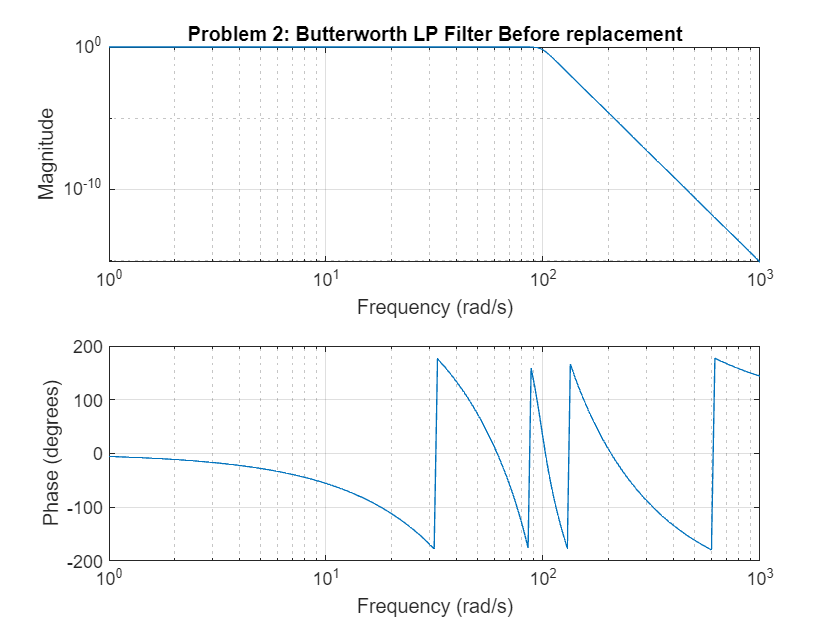

freqs(c,d);
title("Problem 2: Butterworth LP Filter Before replacement");


%problem 2 part b: equivalent digital filter hbiz using bilinear
%transformation method.

%since the above has already been handled, we can simply use the bilinear
%formula within matlab to display the majority of what we are looking for
%in this second part.
[bbi, abi] = bilinear(c, d, Fs2);


%since we are requested to compute the filter coefficients abi and bbi,
%they are listed below for viewing:
abi

abi =     1.0000  -10.3775   50.7885 -155.3728  332.0391 -524.7415  633.1947 -593.7867  436.1174 -250.7802  111.9421  -38.0804    9.5537   -1.6684    0.1813   -0.0092


bbi

bbi = 1.0e-06 *

    0.0001    0.0011    0.0076    0.0329    0.0987    0.2172    0.3621    0.4655    0.4655    0.3621    0.2172    0.0987    0.0329    0.0076    0.0011    0.0001


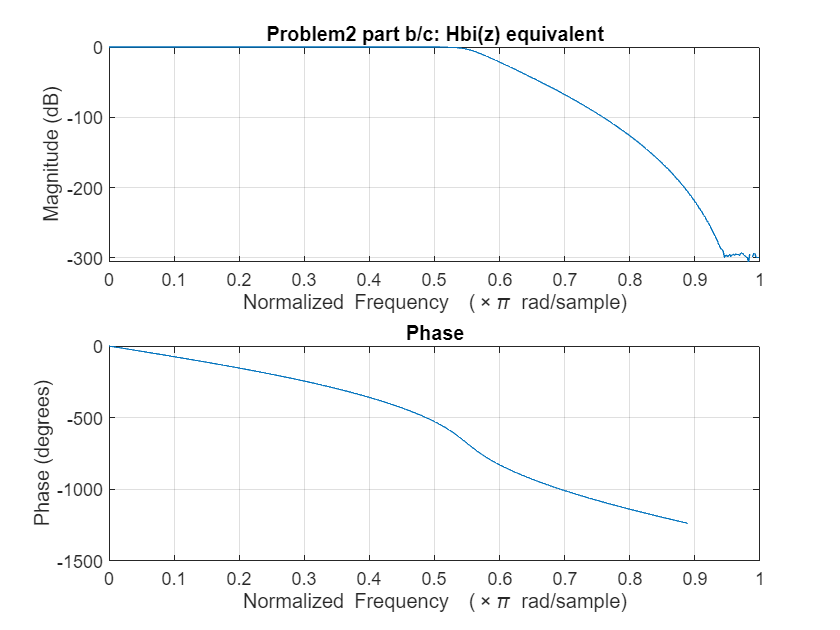

%now, we need to convert these items into ztransform and use zmapping to
%display what we are looking for as the new replacement to the butterworth
%filter.

%using slideset 21 slide 11 which is Table 10.7 from the textbook as
%reference for the lowpass we are trying to build:
wplp = 0.7*pi; %given earlier as the cuttoff...
a = sin((wp - wplp)/2)/sin((wp + wplp)/2);
Nz = [-a 1];
Dz = [1 -a];

[bh,ah] = zmapping(bbi,abi,Nz,Dz);
freqz(bh,ah);
title("Problem2 part b/c: Hbi(z) equivalent");

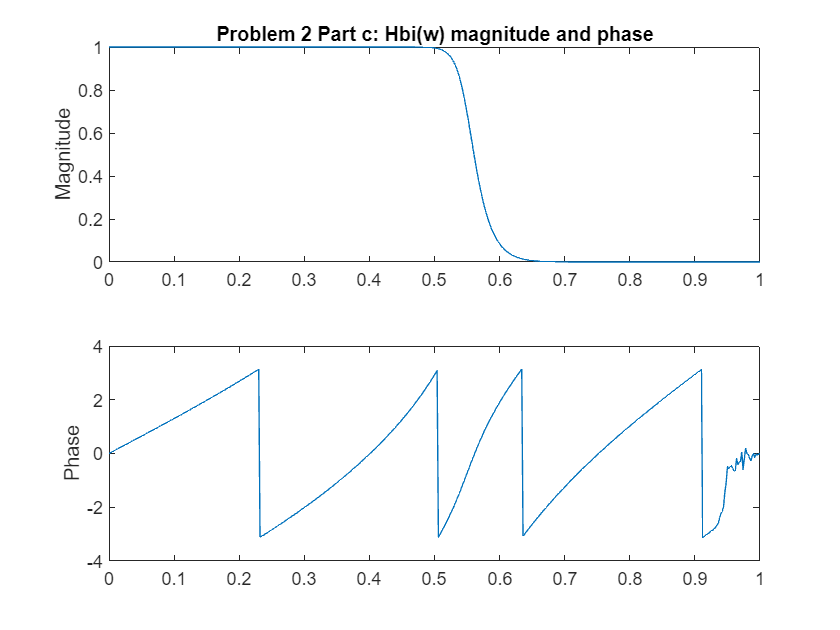

%problem 2 part c: now plot the magnitude and phase response of Hbi(w)
%now using freqz_m which was developed in class/lab, we can display the w
%version of this equation.
[db, mag, pha, grd, w] = freqz_m(bh,ah);
figure;
subplot(2,1,1);
plot(w/pi,mag);
ylabel('Magnitude');
title('Problem 2 Part c: Hbi(w) magnitude and phase');

subplot(2,1,2);
plot(w/pi, pha);
ylabel('Phase');

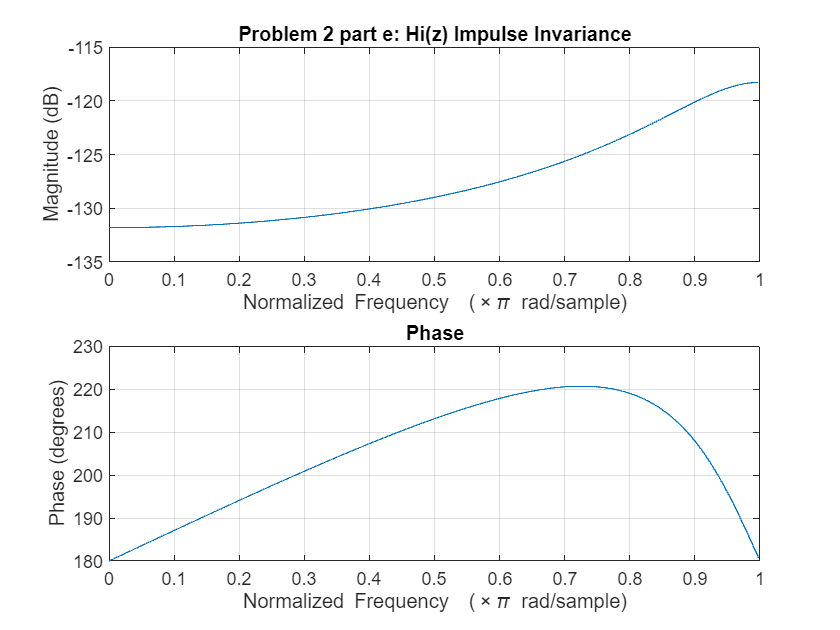

%Problem 2 part d:
% ind = find(abs(h) < sqrt(1/2), 1, 'first'); %allow for an accurate slope to be determined
% slope = (abs(h(ind)) - abs(h(ind - 1))) / (w(ind) - w(ind - 1)); %should give me the slope at a specific point in the graph
% w_3dB = ( sqrt(1/2) - abs(h(ind - 1)) + slope * w(ind - 1) ) / slope %and give me the result of the -3db point on the graph...



%problem 2 part e: Hi(z) using impulse invariance method
%note that we will run back to where we are creating the butterworth filter
%to be able to display this now with impulse invariance

% Impulse Invariance transformation:
[bi,ai] = imp_invr(c,d,Fs);

%using slideset 21 slide 11 which is Table 10.7 from the textbook as
%reference for the lowpass we are trying to build:
wplp = 0.7*pi; %given earlier as the cuttoff...
a = sin((wp - wplp)/2)/sin((wp + wplp)/2);
Nz = [-a 1];
Dz = [1 -a];

[binv,ainv] = zmapping(bi,ai,Nz,Dz);
figure;
freqz(binv,ainv);
title('Problem 2 part e: Hi(z) Impulse Invariance');

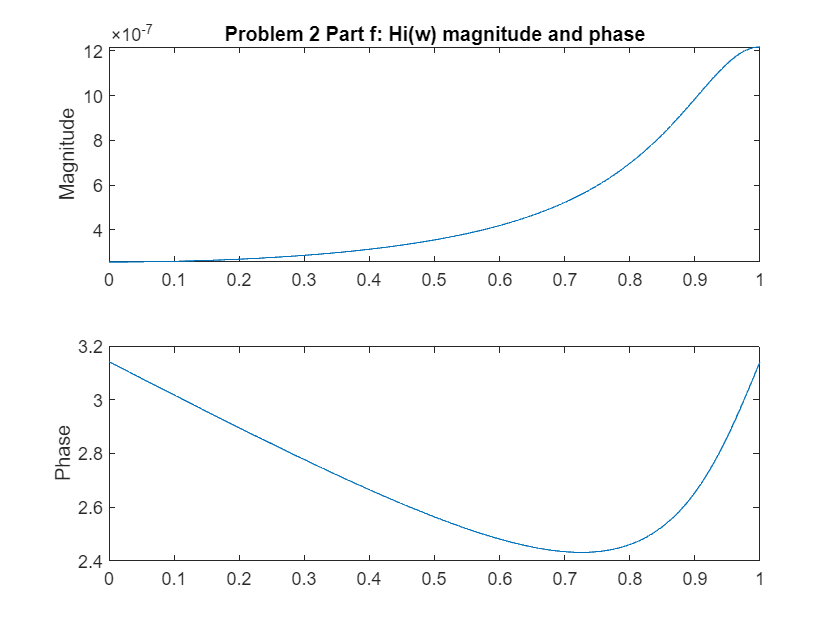

%Problem 2 part f: now to plot the magnitude and phase reponse of Hi(w)
[db2, mag2, pha2, grd2, w2] = freqz_m(binv,ainv);
h = freqz(binv, ainv);
figure;
subplot(2,1,1);
plot(w/pi,mag2);
ylabel('Magnitude');
title('Problem 2 Part f: Hi(w) magnitude and phase');

subplot(2,1,2);
plot(w/pi, pha2);
ylabel('Phase');

%problem 2 part g: 
% linear approximation of 3 dB cutoff frequency
% ind = find(abs(h) < sqrt(1/2), 1, 'first'); %allow for an accurate slope to be determined
% slope = (abs(h(ind)) - abs(h(ind - 1))) / (w(ind) - w(ind - 1)); %should give me the slope at a specific point in the graph
% w_3dB = ( sqrt(1/2) - abs(h(ind - 1)) + slope * w(ind - 1) ) / slope %and give me the result of the -3db point on the graph...



%Problem 2 part h: compare the magnitude of the frequency repsonse of
%Hbi(w) and Hi(w),  which filter has better mangnitude response.

%based of of the magnitude responses of both of these filters, Hbi(w) has
%the better response than the impulse invariance because there is a change
%in the filter type which is not wanted. Bilinear is the best optino here
%as not only does it give us the response we like, but it always works as
%expected on IIR filters.


## Problem 3

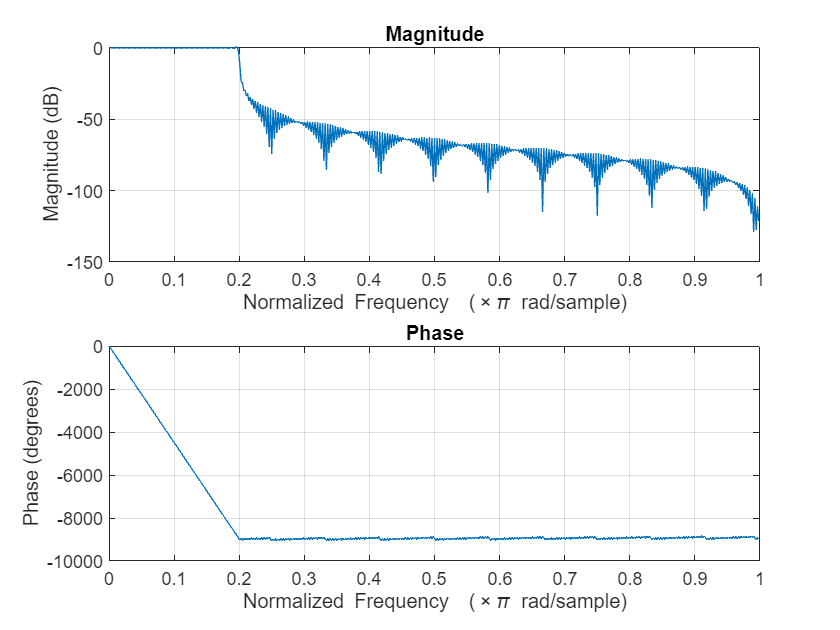

Fs3 = 15000; %sampling rate to be send out
Ts3 = 1/Fs3;

%need to design a frequency converter that can make the conversion without
%aliasing.

%problem 3 part a: what are the lowest values for the interpolation value I
%and decimation value D of the converter?

%note that the original sample length was 10kHz, and we are wanting to go
%up to 15kHz for sending the signal out. this is a change of 1/3 from the
%original sampling frequency.

%also note that interpolation increases the frequency sampling rate while
%decimation decreases the frequency sampling rate.

%based on this, we can detemine the I and D values, which since it takes
%3/2 * 10kHz to achieve 15kHz, we know that 2/3 is our fraction resulting
%in:

I = 3; D = 2;

%Problem 3 part b: design a FIR digital filter Hfs(w) that can be used to
%prevent aliasing from occuring in this conversion process. Find the cutoff
%frequency here as well.

%a simple ideal_lp should suffice for this requirest to prevent
%aliasing....
M = 500; %need to find how I got this...
wc3 = 0.2*pi; %assuming this cuttoff
Hfsw = ideal_lp(wc, M);
freqz(Hfsw);

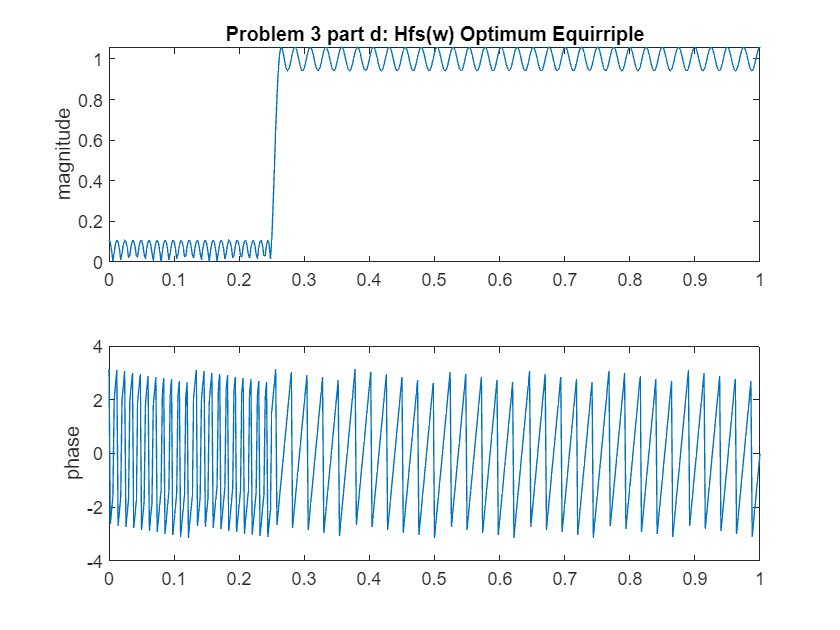



%problem 3 part c: use optimum equi-ripple, compute the filter coefficents
%given the specs below:
Rp = 1;
As = 20;
Tbw = 0.04*pi;
%need the cutoff from part b here as well as a requirement
wp1 = wc3 + (df/2); %need to get the passband using past df value here
f = [ wp1 ws1] ./ pi; %finding the frequency range in radians
%now refering to the slides again to obtain the values needed to run
%firpmord!
a = [0 1 ];
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp));
d2 = db2mag(-As)*(1+d1);
d = [d2 d1 ];

[M, fo, ao, W] = firpmord(f,a,d);
h = firpm(M, fo, ao, W);
[db, mag, pha, grd, w] = freqz_m(h,[1]);

%problem 3 part d: plot the magnitude and phae response of the filter
%designed:
figure;
subplot(2,1,1);
plot(w/pi,mag);
ylabel('magnitude');
title('Problem 3 part d: Hfs(w) Optimum Equirriple')
subplot(2,1,2);
plot(w/pi, pha);
ylabel('phase');

%now do the specs align?
As = -round(max(db(1:1:ws1/delta_w-1))) % Min Stopband attenuation for first stopband

As = 4


%not yet...but adjustments are to be made until As = 20!


%problem 3 part e: what is the bandwidth occupied by the converted signal
%in the discrete time frequency domain (in w)?

%Based on the fact that the original spectrum ranged for 2pi, and that our
%fractional conversion was 3/2, I believe that the output bandwidth should
%be 3pi/2.

## Required Functions and Extras

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end

function [db,mag,pha,grd,w] = freqz_m(b,a); 
% Modified version of freqz subroutine 
% ------------------------------------ 
% [db,mag,pha,grd,w] = freqz_m(b,a); 
% db = Relative magnitude in dB computed over 0 to pi radians 
% mag = absolute magnitude computed over 0 to pi radians 
% pha = Phase response in radians over 0 to pi radians 
% grd = Group delay over 0 to pi radians 
% w = 501 frequency samples between 0 to pi radians 
% b = numerator polynomial of H(z) (for FIR: b=h) 
% a = denominator polynomial of H(z) (for FIR: a=[1]) 
%
[H,w] = freqz(b,a,1000,'whole'); 
H = (H(1:1:501))'; w = (w(1:1:501))';
mag = abs(H); 
db = 20*log10((mag)/max(mag)); 
pha = angle(H); 
grd = grpdelay(b,a,w); 
end

function [b,a] = afd_butt(Wp,Ws,Rp,As);
% Analog Lowpass Filter Design: Butterworth
% -----------------------------------------
% [b,a] = afd_butt(Wp,Ws,Rp,As);
% b = Numerator coefficients of Ha(s)
% a = Denominator coefficients of Ha(s)
% Wp = Passband edge frequency in rad/sec; Wp > 0
% Ws = Stopband edge frequency in rad/sec; Ws > Wp > 0
% Rp = Passband ripple in +dB; (Rp > 0)
% As = Stopband attenuation in +dB; (As > 0)
%
if Wp <= 0
error('Passband edge must be larger than 0')
end
if Ws <= Wp
error('Stopband edge must be larger than Passband edge')
end
if (Rp <= 0) | (As < 0)
error('PB ripple and/or SB attenuation ust be larger than 0')
end
N = ceil((log10((10^(Rp/10)-1)/(10^(As/10)-1)))/(2*log10(Wp/Ws)));
fprintf('\n*** Butterworth Filter Order = %2.0f \n',N)
OmegaC = Wp/((10^(Rp/10)-1)^(1/(2*N)));
[b,a]=u_buttap(N,OmegaC);
end

function [b,a] = u_buttap(N,Omegac);
% Unnormalized Butterworth Analog Lowpass Filter Prototype
% --------------------------------------------------------
% [b,a] = u_buttap(N,Omegac);
% b = numerator polynomial coefficients of Ha(s)
% a = denominator polynomial coefficients of Ha(s)
% N = Order of the Butterworth Filter
% Omegac = Cutoff frequency in radians/sec
%
[z,p,k] = buttap(N);
p = p*Omegac;
k = k*Omegac^N;
B = real(poly(z));
b = k*B; a = real(poly(p));
end

function [bz,az] = zmapping(bZ,aZ,Nz,Dz)
% Frequency band Transformation from Z-domain to z-domain
% -------------------------------------------------------
% [bz,az] = zmapping(bZ,aZ,Nz,Dz)
% performs:
%           b(z)  b(Z)|
%          ---- = ----|     N(z)
%          a(z)   a(Z)|@Z = ----
%                           D(z)

bNzord = (length(bZ)-1)*(length(Nz)-1);
aDzord = (length(aZ)-1)*(length(Dz)-1);
bzord = length(bZ)-1; azord = length(aZ)-1;
bz = zeros(1,bNzord+1);
for k = 0:bzord
    pln = [1];
    for l = 0:k-1
        pln = conv(pln,Nz);
    end
    pld = [1];

    for l = 0:bzord-k-1
        pld = conv(pld,Dz);
    end
    bz = bz+bZ(k+1)*conv(pln,pld);
end
az = zeros(1,aDzord+1);
for k = 0:azord
    pln = [1];
    for l = 0:k-1
        pln = conv(pln,Nz);
    end
    pld = [1];
    for l = 0:azord-k-1
        pld = conv(pld,Dz);
    end
    az = az+aZ(k+1)*conv(pln,pld);
end
end

function [b,a] = imp_invr(c,d,T)
%Impuse Invanriance Transformation from Analog to Digital Filter
% ----------------------------------------------------
% [b,a] = imp_invr(c,d,T)
% b = Numerator polynomial in z^(-1) of the digital filter
% a = Denominator polynomial in z^(-1) of the digital filter
% c = Numerator polynomial in s of the analog filter
% d = Denominator polynomial in s of the analog filter
% T = Sampling (transformation) parameter
%

[R, p, k] = residue(c,d);
p = exp(p*T);
[b,a] = residuez(R,p, k);
b = real(b'); a = real(a');
end
